clear all
close all
clc

MN1 - Compute the Thévenin between 1 and 2 terminals

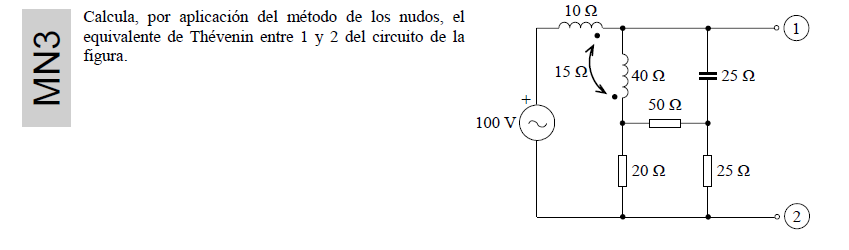

Resolution method

z1=20

z1 = 20

z2=50

z2 = 50

z3=25

z3 = 25

z4=-25*1i

z4 = -0.0000 - 25.0000i

z5=1i*10

z5 = 0.0000 + 10.0000i

z6=1i*40

z6 = 0.0000 + 40.0000i

zm=1i*15

zm = 0.0000 + 15.0000i

Matrix (A) and independent vector (B) definition Ax=B

A=[ 0 0 0 0 -1 0 1;
    0 1/z4 0 -1/z4 1 -1 0;
    0 0 1/z1+1/z2 -1/z2 0 1 0;
    0 -1/z4 -1/z2 1/z2+1/z3+1/z4 0 0 0;
    -1 1 0 0 -z5 -zm 0;
    0 -1 1 0 -zm -z6 0;
    1 0 0 0 0 0 0]

A =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0400i   0.0000 + 0.0000i   0.0000 - 0.0400i   1.0000 + 0.0000i  -1.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0700 + 0.0000i  -0.0200 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 - 0.0400i  -0.0200 + 0.0000i   0.0600 + 0.0400i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
  -1.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 -10.0000i   0.0000 -15.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 -15.0000i   0.0000 -40.0000i   0.0000 + 0.0000i
   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


Solving the system of equations


B=[0;0;0;0;0;0;100]

B =      0
     0
     0
     0
     0
     0
   100


sol=inv(A)*B

sol = 	1.0e+02 *

   1.0000 + 0.0000i
   0.7433 - 0.0883i
   0.0408 - 0.1828i
   0.2507 + 0.2675i
  -0.0121 - 0.0016i
   0.0022 + 0.0181i
  -0.0121 - 0.0016i


Z=inv(A)

Z =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i
   0.0000 + 0.0000i   1.5698 + 2.6234i   4.7263 + 0.9468i   0.5086 + 1.0231i   0.7433 - 0.0883i  -0.3207 - 0.0458i   0.7433 - 0.0883i
   0.0000 + 0.0000i   4.7263 + 0.9468i  15.1966 + 2.9959i   4.9851 + 0.8261i   0.0408 - 0.1828i   0.0359 - 0.1932i   0.0408 - 0.1828i
   0.0000 + 0.0000i   0.5086 + 1.0231i   4.9851 + 0.8261i  12.5002 - 7.7191i   0.2507 + 0.2675i  -0.0990 - 0.2122i   0.2507 + 0.2675i
   0.0000 + 0.0000i   0.7433 - 0.0883i   0.0408 - 0.1828i   0.2507 + 0.2675i  -0.0121 - 0.0016i   0.0022 + 0.0181i  -0.0121 - 0.0016i
   0.0000 + 0.0000i  -0.3207 - 0.0458i   0.0359 - 0.1932i  -0.0990 - 0.2122i   0.0022 + 0.0181i  -0.0045 + 0.0093i   0.0022 + 0.0181i
   1.0000 + 0.0000i   0.7433 - 0.0883i   0.0408 - 0.1828i   0.2507 + 0.2675i  -0.0121 - 0.0016i   0.0022 + 0.0181i  -0.0121 - 0.0016i



uth=sol(2) % Thevenin computed with 'Terminal 2'

uth = 74.3343 - 8.8263i

abs(uth)

ans = 74.8565

angle(uth)*180/pi

ans = -6.7715


Zth=Z(2,2)

Zth = 1.5698 + 2.6234i